clc; clear;
% Ryan Mittelstadt

% -------------------------- Part A --------------------------
% Constants
m = 3700 + 8500;  % Mass (kg)
a = 0.75;         % Engine imbalance (m)

%  Parameter Ranges
zeta_range = linspace(0, 1, 50);           % Damping ratio range
omega_range = linspace(0.01, (2*pi*3100)/60, 100);  % Omega range (rad/s)
k_range = linspace(1e3, 3e10, 100);       % Stiffness range (N/m)

valid_k = [];  % Store valid k values that satisfy the condition for all zeta

for k_idx = 1:length(k_range) % Loop through stiffness k
    k = k_range(k_idx);
    valid_zeta = true;  % Assume valid for all zetas until proven otherwise

    for i = 1:length(zeta_range) % Loop through zeta
        zeta = zeta_range(i);
        
        valid_omega = true;  % Default state for AR < 0.05 condition

        for w = 1:length(omega_range) % Loop through omega
            omega = omega_range(w);
            
            % Compute amplification ratio for current omega, k, and zeta
            c = zeta * 2 * sqrt(k * m);
            amp_ratio = (m * omega^2 * a) / sqrt((k - m * omega^2)^2 + omega^2 *c);

            if amp_ratio >= 0.05 % AR condition
                valid_omega = false;
                break;
            end
        end
        
        % If any zeta fails, the k is invalid for this case
        if ~valid_omega
            valid_zeta = false;
            break;
        end
    end
    
    % If the k value is valid for all zeta values, store it
    if valid_zeta
        valid_k(end+1) = k;
    end
end

% Output the range of k values that satisfy the condition for all zetas
if ~isempty(valid_k)
    k_min_all_zeta = min(valid_k);
    k_max_all_zeta = max(valid_k);
    fprintf('\nValid stiffness range for all zeta values (omega = 3100 rpm):\n');
    fprintf('k_min = %.4e | k_max = %.4e\n', k_min_all_zeta, k_max_all_zeta);
else
    fprintf('\nNo valid k values found that satisfy the condition for all zeta values.\n');
end


Valid stiffness range for all zeta values (omega = 3100 rpm):


k_min = 2.0606e+10 | k_max = 3.0000e+10


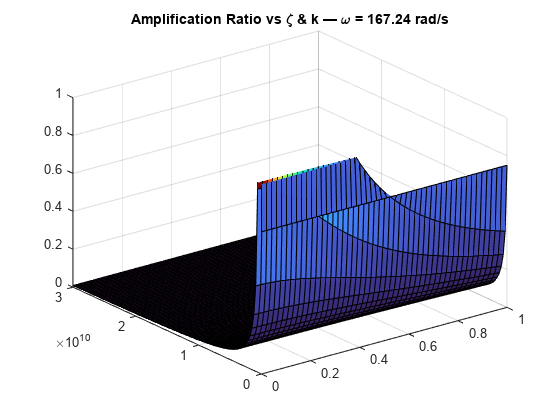


% -------------------------- Visualization: Animated Surface --------------------------
% Set up meshgrid for zeta and k
[ZETA, K] = meshgrid(zeta_range, k_range);

% Set up figure for animation
figure;
colormap turbo;
xlabel('\zeta');
ylabel('k (N/m)');
zlabel('Amplification Ratio');
title('Amplification Ratio vs \zeta & k — varying \omega');
view(45, 30);  % 3D view

% Initial frame for animation (prevents two graphs from showing)
omega = omega_range(1);
AMP = (m * omega^2 * a) ./ sqrt((K - m * omega^2).^2 + omega^2 * (ZETA * 2 .* sqrt(K * m)).^2);
h = surf(ZETA, K, AMP);
zlim([0 1]);

% Animate over omega range
for w = 2:length(omega_range)
    omega = omega_range(w);
    AMP = (m * omega^2 * a) ./ sqrt((K - m * omega^2).^2 + omega^2 * (ZETA * 2 .* sqrt(K * m)).^2);
    set(h, 'ZData', AMP);
    zlim([0 1]);  % Lock axis every frame
    title(sprintf('Amplification Ratio vs \\zeta & k — \\omega = %.2f rad/s', omega));
    drawnow;
end


% -------------------------- Part B --------------------------
% Find Amplification Ratios for zeta sweep given k from problem a
omega_B = (pi/2 * 2200)/60; % rad/sec
m_b = 3700 + 8500 * (0.1); % kg

% Reduce zeta range for part B
zeta_range = linspace(0, 1, 10);
amp_ratios_zeta = zeros(size(zeta_range));

% Calculate Amplification Ratio (zeta sweep)
for i = 1:length(zeta_range)
    zeta = zeta_range(i);
    amp_ratios_zeta(i) = (m_b * omega_B^2 * a) / ...
        sqrt((k_min_all_zeta - m_b * omega_B^2)^2 + omega_B^2 * (2 * zeta * sqrt(k_min_all_zeta * m_b))^2);
end

% Display results
fprintf('\nAmp. ratios for each zeta (2200 rpm, k = %.4e N/m):\n', k_min_all_zeta);


Amp. ratios for each zeta (2200 rpm, k = 2.0606e+10 N/m):


for i = 1:length(zeta_range)
    fprintf('Zeta = %.2f | Amplification Ratio=%.8f\n', zeta_range(i), amp_ratios_zeta(i));
end

Zeta = 0.00 | Amplification Ratio=0.00054977
Zeta = 0.11 | Amplification Ratio=0.00054976
Zeta = 0.22 | Amplification Ratio=0.00054973
Zeta = 0.33 | Amplification Ratio=0.00054968
Zeta = 0.44 | Amplification Ratio=0.00054961
Zeta = 0.56 | Amplification Ratio=0.00054952
Zeta = 0.67 | Amplification Ratio=0.00054941
Zeta = 0.78 | Amplification Ratio=0.00054928
Zeta = 0.89 | Amplification Ratio=0.00054913
Zeta = 1.00 | Amplification Ratio=0.00054896



% -------------------------- Part C --------------------------
max_amp_ratio = max(amp_ratios_zeta);
fprintf('\nWorst amp. ratio (2200 rpm, k=%.4e N/m): %.8f\n', k_min_all_zeta, max_amp_ratio)


Worst amp. ratio (2200 rpm, k=2.0606e+10 N/m): 0.00054977
